# Atividade 13_02

Otávio Baziewicz Filho - 1942808

clc; clear; close all;

## Detecção de bordas em imagens coloridas

Crie um script para realizar a detecção de bordas de uma imagem colorida à sua escolha. Mostre a imagem original e a saída da detecção de bordas.

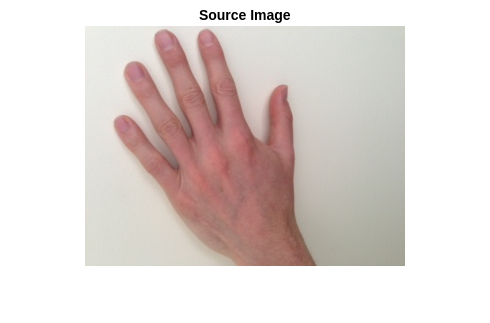

img = imread("hands2.jpg");

r = img(:,:,1);
g = img(:,:,2);
b = img(:,:,3);

rc = edge(r, "canny");
gc = edge(g, "canny");
bc = edge(b, "canny");

processedImage1 = rc | gc | bc;
processedImage2 = edge(rgb2gray(img), "canny");

figure, imshow(img), title("Source Image")

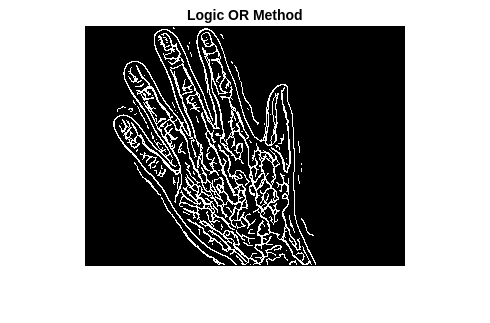

figure, imshow(processedImage1), title("Logic OR Method")

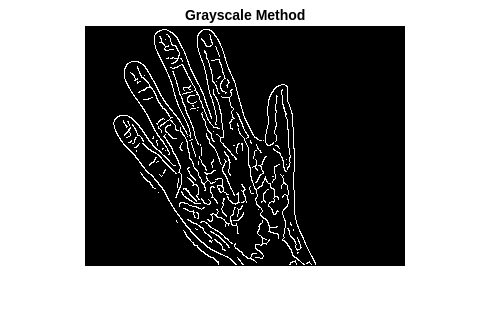

figure, imshow(processedImage2), title("Grayscale Method")    